%Plots the tuning curves of the membrane potentials across stimulus
%directions for current clamp experiments with different current injections

%***IMPORTANT*** - PRIOR TO RUNNING THIS SCRIPT make sure you:
%     1) Run TuningCurveWidth_CurrentInjection.mlx to select the depolarized 
%         and hyperpolarized epoch numbers for new cells
%     2) Run Preprocessing_CurrentClampForIgor.m in order to create a 
%         subdirectory for this cell with the raw data for depolarized and 
%         hyperpolarized epochs
%     3) Use ExtractVms.mlapp to extract underlying membrane fluctuations
%         from both the depolarized and hyperpolarized epochs.
        



%Load the data. Data for each cell is kept in its own directory at
%.../Completed_Analysis/WholeCell/CurrentInjection/MembraneTracesForIgor
dataPath = 'C:\Users\mrsco\Box\Completed_Analysis\WholeCell\CurrentInjections\MembraneTracesForIgor';

%Load the .mat files that specify which cells are up cells, which cells are
%down cells and have the stimulus direction for each epoch for each cell.
%These files are originally created when running
%TuningCurveWidt_CurrentInjection.mlx and are saved from that workspace.
%If new cells are added update these files.
load(fullfile(dataPath, 'UpEpochNums.mat'))
load(fullfile(dataPath, 'DownEpochNums.mat'))

%Now grab the data
%ups first
upAUCs_DSI_hyperpolarized = [];
upMax_DSI_hyperpolarized = [];
upAUCs_Area_hyperpolarized = [];
upMax_Area_hyperpolarized = [];
upAUCs_NormedArea_hyperpolarized = [];
upMax_NormedArea_hyperpolarized = [];
upAUCs_PDResponse_hyperpolarized = [];
upMax_PDResponse_hyperpolarized = [];


upAUCs_DSI_depolarized = [];
upMax_DSI_depolarized = [];
upAUCs_Area_depolarized = [];
upMax_Area_depolarized = [];
upAUCs_NormedArea_depolarized = [];
upMax_NormedArea_depolarized = [];
upAUCs_PDResponse_depolarized = [];
upMax_PDResponse_depolarized = [];

%Exclude these cells:
cantExtractVmFrom = {'SHOKR80Lc7', 'SHOKR80Lc11', 'SHOKR81Lc7', 'SHOKR81Lc1',...
    'SHOKR81Lc8', 'SHOKR84Lc2'};
%cantExtractVmFrom = {};
requirements = @(cname, dataPath) exist([dataPath, '\', cname], 'dir')...
    && ~ismember(cname, cantExtractVmFrom);%&& (contains(cname, '84') || contains(cname, '80'));

for c = 1:size(upEpochNumsByCell, 1)
    cname = upEpochNumsByCell{c, 1};
    if ~requirements(cname, dataPath)
        continue
    end
    
    try
        load(fullfile(dataPath, cname, 'depolarized_extractedVms.mat'))
        depolarizedTraces = extractedTraces;
        load(fullfile(dataPath, cname, 'hyperpolarized_extractedVms.mat'))
        hyperpolarizedTraces = extractedTraces;
        clear extractedTraces;
    catch
        continue
    end
    
    hyperpolarizedDirections = upEpochNumsByCell{c, 3};
    depolarizedDirections = upEpochNumsByCell{c, 5};
    
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections);
    
    %hyperpolarized condition
    upAUCs_DSI_hyperpolarized = [upAUCs_DSI_hyperpolarized,output.DSI_AUCs];
    upMax_DSI_hyperpolarized = [upMax_DSI_hyperpolarized, output.DSI_MaxResponses];
    upAUCs_Area_hyperpolarized = [upAUCs_Area_hyperpolarized, output.TotalArea_AUCs];
    upMax_Area_hyperpolarized = [upMax_Area_hyperpolarized, output.TotalArea_MaxResponses];
    upAUCs_NormedArea_hyperpolarized = [upAUCs_NormedArea_hyperpolarized, output.NormalizedArea_AUCs];
    upMax_NormedArea_hyperpolarized = [upMax_NormedArea_hyperpolarized, output.NormalizedArea_MaxResponses];
    upAUCs_PDResponse_hyperpolarized = [upAUCs_PDResponse_hyperpolarized, output.PDResponse_AUCs];
    upMax_PDResponse_hyperpolarized = [upMax_PDResponse_hyperpolarized, output.PDResponse_MaxResponses];
    
    %depolarized condition
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections);    
    upAUCs_DSI_depolarized = [upAUCs_DSI_depolarized,output.DSI_AUCs];
    upMax_DSI_depolarized = [upMax_DSI_depolarized, output.DSI_MaxResponses];
    upAUCs_Area_depolarized = [upAUCs_Area_depolarized, output.TotalArea_AUCs];
    upMax_Area_depolarized = [upMax_Area_depolarized, output.TotalArea_MaxResponses];
    upAUCs_NormedArea_depolarized = [upAUCs_NormedArea_depolarized, output.NormalizedArea_AUCs];
    upMax_NormedArea_depolarized = [upMax_NormedArea_depolarized, output.NormalizedArea_MaxResponses];
    upAUCs_PDResponse_depolarized = [upAUCs_PDResponse_depolarized, output.PDResponse_AUCs];
    upMax_PDResponse_depolarized = [upMax_PDResponse_depolarized, output.PDResponse_MaxResponses];
end


%downs second
downAUCs_DSI_hyperpolarized = [];
downMax_DSI_hyperpolarized = [];
downAUCs_Area_hyperpolarized = [];
downMax_Area_hyperpolarized = [];
downAUCs_NormedArea_hyperpolarized = [];
downMax_NormedArea_hyperpolarized = [];
downAUCs_PDResponse_hyperpolarized = [];
downMax_PDResponse_hyperpolarized = [];

downAUCs_DSI_depolarized = [];
downMax_DSI_depolarized = [];
downAUCs_Area_depolarized = [];
downMax_Area_depolarized = [];
downAUCs_NormedArea_depolarized = [];
downMax_NormedArea_depolarized = [];
downAUCs_PDResponse_depolarized = [];
downMax_PDResponse_depolarized = [];

for c = 1:size(downEpochNumsByCell, 1)
    cname = downEpochNumsByCell{c, 1};
    if ~requirements(cname, dataPath)
        continue
    end
    
   try
        load(fullfile(dataPath, cname, 'depolarized_extractedVms.mat'))
        depolarizedTraces = extractedTraces;
        load(fullfile(dataPath, cname, 'hyperpolarized_extractedVms.mat'))
        hyperpolarizedTraces = extractedTraces;
        clear extractedTraces;
    catch
        continue
    end
    
    hyperpolarizedDirections = downEpochNumsByCell{c, 3};
    depolarizedDirections = downEpochNumsByCell{c, 5};
    
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections);
    
    %hyperpolarized condition
    downAUCs_DSI_hyperpolarized = [downAUCs_DSI_hyperpolarized,output.DSI_AUCs];
    downMax_DSI_hyperpolarized = [downMax_DSI_hyperpolarized, output.DSI_MaxResponses];
    downAUCs_Area_hyperpolarized = [downAUCs_Area_hyperpolarized, output.TotalArea_AUCs];
    downMax_Area_hyperpolarized = [downMax_Area_hyperpolarized, output.TotalArea_MaxResponses];
    downAUCs_NormedArea_hyperpolarized = [downAUCs_NormedArea_hyperpolarized, output.NormalizedArea_AUCs];
    downMax_NormedArea_hyperpolarized = [downMax_NormedArea_hyperpolarized, output.NormalizedArea_MaxResponses];
    downAUCs_PDResponse_hyperpolarized = [downAUCs_PDResponse_hyperpolarized, output.PDResponse_AUCs];
    downMax_PDResponse_hyperpolarized = [downMax_PDResponse_hyperpolarized, output.PDResponse_MaxResponses];
    
    %depolarized condition
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections);    
    downAUCs_DSI_depolarized = [downAUCs_DSI_depolarized,output.DSI_AUCs];
    downMax_DSI_depolarized = [downMax_DSI_depolarized, output.DSI_MaxResponses];
    downAUCs_Area_depolarized = [downAUCs_Area_depolarized, output.TotalArea_AUCs];
    downMax_Area_depolarized = [downMax_Area_depolarized, output.TotalArea_MaxResponses];
    downAUCs_NormedArea_depolarized = [downAUCs_NormedArea_depolarized, output.NormalizedArea_AUCs];
    downMax_NormedArea_depolarized = [downMax_NormedArea_depolarized, output.NormalizedArea_MaxResponses];
    downAUCs_PDResponse_depolarized = [downAUCs_PDResponse_depolarized, output.PDResponse_AUCs];
    downMax_PDResponse_depolarized = [downMax_PDResponse_depolarized, output.PDResponse_MaxResponses];
end

## Plot the data and get the results

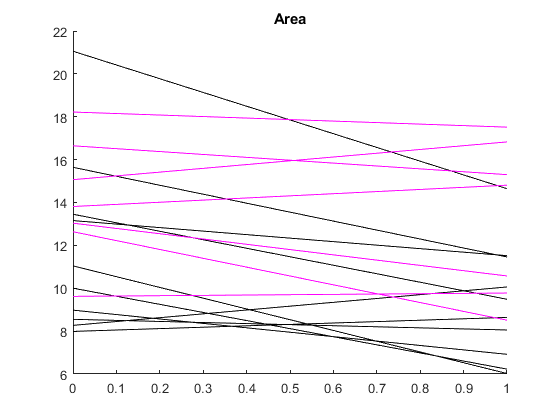

figure
title('Area')
hold on
for i = 1:numel(upMax_DSI_hyperpolarized)
    plot([0, 1], [upMax_Area_hyperpolarized(i), upMax_Area_depolarized(i)], 'k')
end
for i = 1:numel(downMax_DSI_hyperpolarized)
     plot([0, 1], [downMax_Area_hyperpolarized(i), downMax_Area_depolarized(i)], 'm')
end

p_area = signrank([downMax_Area_hyperpolarized-downMax_Area_depolarized,...
    upMax_Area_hyperpolarized-upMax_Area_depolarized])

p_area = 0.0168

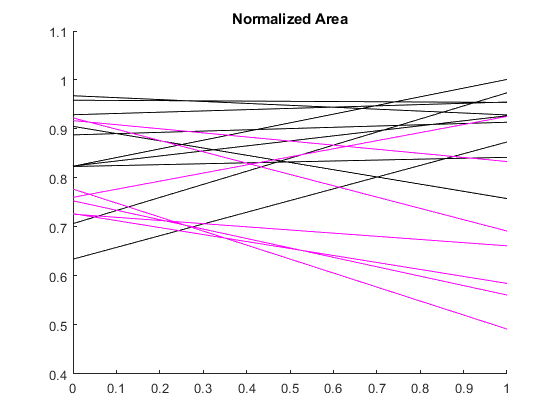


figure
title('Normalized Area')
hold on
for i = 1:numel(upMax_DSI_hyperpolarized)
    plot([0, 1], [upMax_NormedArea_hyperpolarized(i), upMax_NormedArea_depolarized(i)], 'k')
end
for i = 1:numel(downMax_DSI_hyperpolarized)
     plot([0, 1], [downMax_NormedArea_hyperpolarized(i), downMax_NormedArea_depolarized(i)], 'm')
end

p_normedArea = signrank([downMax_NormedArea_hyperpolarized-downMax_NormedArea_depolarized,...
    upMax_NormedArea_hyperpolarized-upMax_NormedArea_depolarized])

p_normedArea = 0.7946

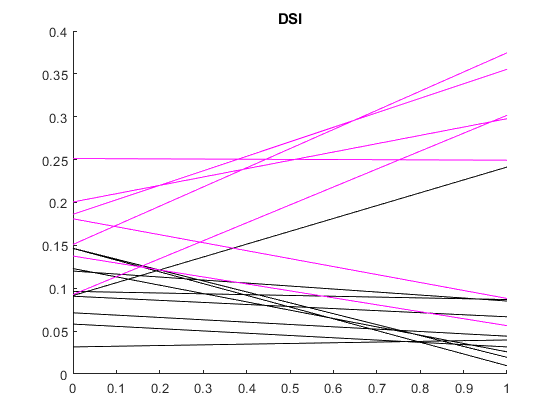


figure
title('DSI')
hold on
for i = 1:numel(upMax_DSI_hyperpolarized)
    plot([0, 1], [upMax_DSI_hyperpolarized(i), upMax_DSI_depolarized(i)], 'k')
end
for i = 1:numel(downMax_DSI_hyperpolarized)
     plot([0, 1], [downMax_DSI_hyperpolarized(i), downMax_DSI_depolarized(i)], 'm')
end

p_DSI = signrank([downMax_DSI_hyperpolarized-downMax_DSI_depolarized,...
    upMax_DSI_hyperpolarized-upMax_DSI_depolarized])

p_DSI = 0.9058